clear

addpath("matlab_functions\")

global defects
defects = {};

#### Add defect to plate

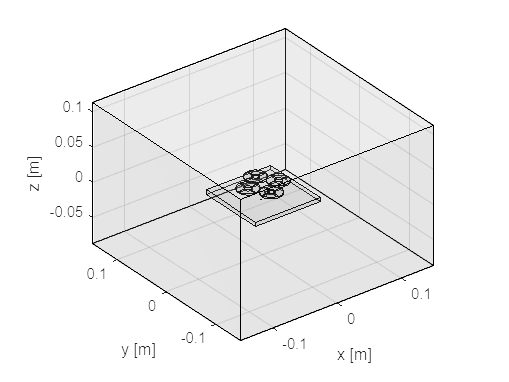

[model, Plate, Coil, Sensor] = myModel;
freqs = [900 225 100 55]; % (Hz)
mesh_size = 2; % 1:finest 9:coarsest

% AddRectangularDefect(model, 5e-3, 0, 4e-3, 4e-3, 0, -3e-3)
% AddCircularDefect(model, 5e-3,0, 8e-3, 0, -3e-3)

figure
ComsolModel('PlotGeometry', model)

#### Compute fields

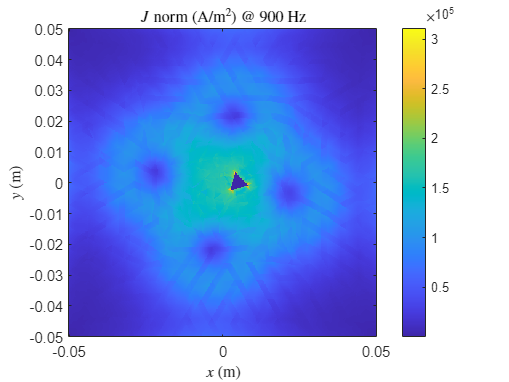

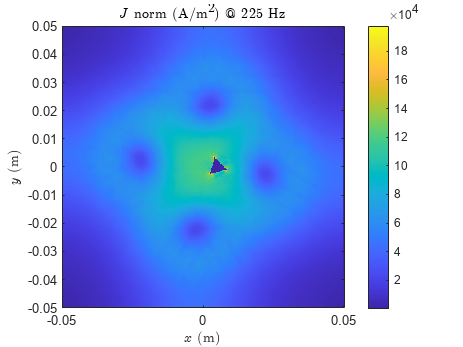

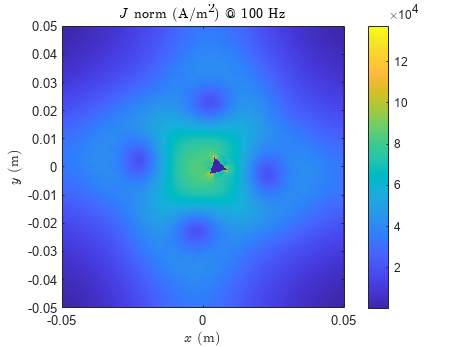

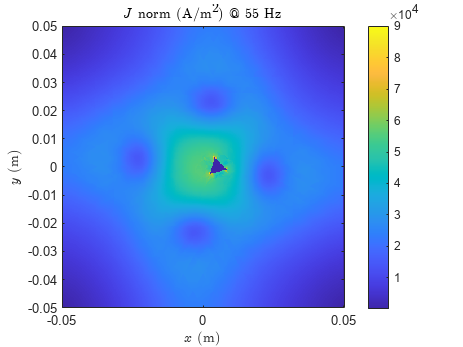

B_data = zeros(length(freqs), size(Sensor.positions,2));

for i = 1:length(freqs)
    model = ComsolModel('SolveCoil', model, Coil, freqs(i), mesh_size);
    
    [x,y,z] = ndgrid( ...
        linspace(-Plate.length/2, Plate.length/2, 500), ...
        linspace(-Plate.length/2, Plate.length/2, 500), ...
        -2e-3 );
    r = [reshape(x,1,[]); reshape(y,1,[]); reshape(z,1,[])];
    J = ComsolModel('InterpField', model, 'J', r);
    
    figure
    imagesc([-Plate.length/2 Plate.length/2],[-Plate.length/2 Plate.length/2], ...
            reshape(vecnorm(J),500,500).')
    colorbar
    axis square xy
    xlabel('$x$ (m)', 'Interpreter','latex')
    ylabel('$y$ (m)', 'Interpreter','latex')
    title(sprintf('$J$ norm (A/m$^2$) @ %d Hz',freqs(i)), 'Interpreter','latex')

    B = ComsolModel('InterpField', model, 'B', Sensor.positions);
    B_data(i,:) = dot(B, Sensor.axes);
end


clear i x y z r J B mesh_size

#### Export sensor data

fname = sprintf('data/B_%s.txt', datetime('now','Format','MMdd-HHmm'));

fid = fopen(fname, 'w');

for i = 1:length(defects)
    fprintf(fid, '%% defect %s\n', jsonencode(defects{i}));
end
for i = 1:length(freqs)
    fprintf(fid, '%% frequency %d Hz\n', freqs(i));
    fprintf(fid, '%s\n', num2str(B_data(i,:)));
end

fclose(fid);

clear fname fid i

function AddRectangularDefect(model, c_x,c_y,dx,dy,z1,z2)

defect.type = 'rectangular';
defect.c_x = c_x;
defect.c_y = c_y;
defect.dx = dx;
defect.dy = dy;
defect.z1 = min(z1,z2);
defect.z2 = max(z1,z2);

global defects
defects{end+1} = defect;

geom = model.component('mod1').geom('geom1');
tag = sprintf('defect%d', length(defects));
block = geom.create(tag, 'Block');
block.set('base', 'center');
block.set('pos', [c_x c_y (z1+z2)/2]);
block.set('size', [dx dy abs(z1-z2)]);

removeFromPlate(model, tag)

end

function AddCircularDefect(model, c_x,c_y,d,z1,z2)

defect.type = 'circular';
defect.c_x = c_x;
defect.c_y = c_y;
defect.d = d;
defect.z1 = min(z1,z2);
defect.z2 = max(z1,z2);

global defects
defects{end+1} = defect;

geom = model.component('mod1').geom('geom1');
tag = sprintf('defect%d', length(defects));
defect = geom.create(tag, 'Cylinder');
defect.set('pos', [c_x c_y min(z1,z2)]);
defect.set('r', d/2);
defect.set('h', abs(z2-z1));

removeFromPlate(model, tag)

end

function AddPolygonalDefect(model, xs,ys,z1,z2)

xs = reshape(xs, 1,[]);
ys = reshape(ys, 1,[]);
if ~(xs(1) == xs(end) && ys(1) == ys(end))
    xs = [xs xs(1)]; 
    ys = [ys ys(1)]; 
end

defect.type = 'polygonal';
defect.xs = xs;
defect.ys = ys;
defect.z1 = min(z1,z2);
defect.z2 = max(z1,z2);

global defects
defects{end+1} = defect;

geom = model.component('mod1').geom('geom1');

tag = sprintf('defect%d', length(defects));

wp = geom.create(strcat(tag,'_wp'), 'WorkPlane');
wp.set('quickz', defect.z1);
wp.set('unite', true);

pol = wp.geom.create(strcat(tag,'_pol'), 'Polygon');
pol.set('source', 'table');
pol.set('table', [xs;ys]');

defect = geom.feature.create(tag, 'Extrude');
defect.selection('input').set(strcat(tag,'_wp'));
defect.set('distance', abs(z2-z1));

removeFromPlate(model, tag)

end

function removeFromPlate(model, geom_tag)

global defects
if length(defects) == 1
    plate_tag = 'plate';
else
    plate_tag = sprintf('dif%d', length(defects)-1);
end

geom = model.component('mod1').geom('geom1');
dif = geom.create(sprintf('dif%d',length(defects)), 'Difference');
dif.selection('input').set(plate_tag);
dif.selection('input2').set(geom_tag);
geom.run

end